Brief summary of this function.

Detailed explanation of this function.

function CLC = clc_settings(Sim)

## Section 1: Settings

### 1.1 Time settings

Choose how often a new control setting is applied. The unit is simulation steps, time depends on the frequency with which FLORIDyn runs (typically one simulation step equals 4s). Choosing 1 will lead to an update at every time step, 5 at every fifth step.

CLC.Time.nS =12; 

Derived time settings, no changes necessary.

CLC.Time.Sections   = max(floor(length(Sim.StartTime:Sim.TimeStep:Sim.EndTime) / CLC.Time.nS),1); % Total number of controlled sections
CLC.Time.SecDur     = Sim.TimeStep * CLC.Time.nS;
CLC.Time.StartTime  = Sim.StartTime + 200;

### 1.2 Control Settings

#### 1.2.1 Basic settings / boundaries

CLC.Con.yawRangeMin     =-33; % in deg
CLC.Con.yawRangeMax     =33;  % in deg
CLC.Set.yawRateLimit    = 0.3; % in deg/s
%CLC.Set.disableYawForLastTurbine = true; % If enabled, the most downstream turbines always align with the main wind direction

#### 1.2.2 Strategy settings

CLC.Con.Strategy            = "yaw_2dof_max_rate_groups_pso";
CLC.Con.DOFpT               = 2; % Degrees of freedom per turbine
%CLC.Con.EnforceYawRateLimit = true;
CLC.Con.tanhYaw             = true; % Weights the power to intrinsically enforce the yaw limit
CLC.Con.horizon_prediction  = 200; % in simulation steps
CLC.Con.horizon_action      = 35;  % in simulation steps, less or equal to prediction horizon
CLC.Con.CostFunction        = "maxPowerOverall";
CLC.Con.InitMethod          = "0 + rand";
CLC.max_iterations          = 20;

#### 1.2.3 Prediction setting

`Weighted constant`: Using state weighting between the OPs to feed in new values at the turbine location. This is equivalent to using no preview, only the information within the current state of the simulation. The trust function is ignored.

`Limited Preview` : Allows the definition of a "trust function" with values between 1 and 0 (1= full knowledge of the wind dir changes ahead, 0=no knowledge). Function is passed as a vector of values with  `[1 x CLC.Con.horizon_prediction]` elements. Below there is an example how this would look like for a linearly declining trust function over a 200s prediction horizon, valuated every 50s.

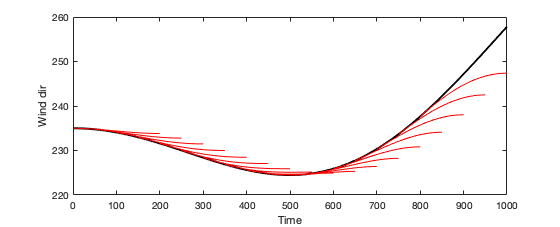

CLC.Con.WindPrediction      = "WeightedConstant";
CLC.Con.TrustFunc           = linspace(1,0,CLC.Con.horizon_prediction);

## Section 2: Output

### Section 2.1 Stored output

Store a csv with the yaw angle and orientation of all turbines

CLC.Con.StoreData = true;
CLC.Out.YawTrajectories = true;

### Section 2.2 Online output

CLC.Out.Online.plotCostGraph = true;

end